clear;
initialConditions;
mdl = 'microgrid_WithESSOpt';

pvDataSet = [0;1];

numOffset = 5;
offset = linspace(1,25,numOffset);
offset = repmat(offset,1,2)';

[xVec,yVec] = meshgrid(offset,pvDataSet);
inputVec = [xVec(:) yVec(:)];
numSim = size(inputVec,1);
inputVec(numOffset*numel(pvDataSet)+1:end,3) = 1;


for i = 1:numSim
    in(i) = Simulink.SimulationInput(mdl);
    in(i) = in(i).setVariable('emsMode',inputVec(i,3));
    in(i) = in(i).setVariable('pvSelect',inputVec(i,2));
    
    costDataOffset = [costData(inputVec(i,1):end); costData(1:inputVec(i,1)-1)];
    in(i) = in(i).setVariable('costDataOffset',costDataOffset);
end
in(1)

ans =   SimulationInput with properties:

          ModelName: 'microgrid_WithESSOpt'
       InitialState: [0×0 Simulink.SimState.ModelSimState]
      ExternalInput: []
    ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
    BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
          Variables: [1×3 Simulink.Simulation.Variable]
          PreSimFcn: []
         PostSimFcn: []
         UserString: ''




out = sim(in, 'ShowSimulationManager', 'on','UseFastRestart',true,'ShowProgress','off');

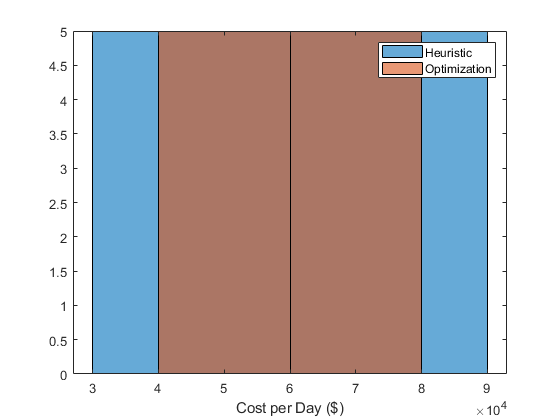

heuristicCost = [];
optCost = [];
for i = 1:numSim
    if i <= numOffset*numel(pvDataSet)
        heuristicCost(end+1) = out(i).logsout{1}.Values.Data(end);
    else
        optCost(end+1)= out(i).logsout{1}.Values.Data(end);
    end
end
histogram(heuristicCost); hold on;
histogram(optCost);
legend('Heuristic','Optimization');
xlabel('Cost per Day ($)'); hold off;